# REGALS analysis of NrdE AEX data

**The data and analysis were originally published in:**

Mackenzie J. Parker, Ailiena O. Maggiolo, William C. Thomas, Albert Kim, Steve P. Meisburger, Nozomi Ando, Amie K. Boal, JoAnne Stubbe. *An endogenous dAMP ligand in Bacillus subtilis class Ib RNR promotes assembly of a noncanonical dimer for regulation by dATP. *PNAS, May 2018, 115 (20), E4594-E4603; DOI: 10.1073/pnas.1800356115

addpath('../matlab/'); % add REGALS code to path

## Load data

load data/NrdE_mix_AEX.mat q I sigma name
fprintf(1,'loaded dataset: %s\n',name);

loaded dataset: RNR_AEX/NrdE_mix_AEX_1_31


x = 1:size(I,2); % x is the frame number

## Set up REGALS calculation

Each component has a concentration and profile regularizer. In this case, there is no regularization of the profiles (all are "simple" type).

Bg1 = Component(...
    Concentration(x,'smooth',...
        'xmin',min(x)-1E-3,...
        'xmax',max(x)+1E-3,...
        'isZeroAtXmin',false,...
        'isZeroAtXmax',false),...
    Profile(q,'simple'));

Bg2 = Component(... %
    Concentration(x,'smooth',...
        'xmin',201-1E-3,...
        'xmax',max(x)+1E-3,...
        'isZeroAtXmin',true,...
        'isZeroAtXmax',false),...
    Profile(q,'simple'));

C1 = Component(...
    Concentration(x,'smooth',...
        'xmin',730,...
        'xmax',1270),...
    Profile(q,'simple'));

C2 = Component(...
    Concentration(x,'smooth',...
        'xmin',1150,...
        'xmax',1600),...
    Profile(q,'simple'));

% create Mixture object and set regularization parameters.
M = Mixture([C1,C2,Bg1,Bg2]);
M.concentrationLambda = M.estimateConcentrationLambda(sigma,[Inf,Inf,8,8]);

## Run REGALS

R = REGALS(I,sigma); % creat REGALS object

% set stopFun to return true when 50 iterations is exceeded
stopFun = @(iter,params) deal(iter >=  50,'maxIter');

updateFun = @(iter,NewMix,params,resid) ...
    fprintf(1,'%2d, x2 = %f, delta_profile = %s\n',...
    iter,params.x2,mat2str(params.delta_profile,3));

% run for 50 iterations
[M1,params,resid] = R.run(M,stopFun,updateFun);

 1, x2 = 1.169934, delta_profile = [389 457 291 71.9]
 2, x2 = 1.040464, delta_profile = [43.6 118 284 65.9]
 3, x2 = 1.023812, delta_profile = [2.2 1.45 47.8 38.2]
 4, x2 = 1.017008, delta_profile = [1.82 0.366 21.2 5.23]
 5, x2 = 1.014626, delta_profile = [0.829 0.181 9.02 2.2]
 6, x2 = 1.013674, delta_profile = [0.558 0.12 4.7 0.734]
 7, x2 = 1.013237, delta_profile = [0.407 0.0799 2.26 0.873]
 8, x2 = 1.013002, delta_profile = [0.309 0.0537 0.994 1.25]
 9, x2 = 1.012855, delta_profile = [0.237 0.0362 0.356 1.51]
10, x2 = 1.012751, delta_profile = [0.182 0.0246 0.0744 1.65]
11, x2 = 1.012669, delta_profile = [0.14 0.0171 0.115 1.72]
12, x2 = 1.012598, delta_profile = [0.109 0.0123 0.178 1.75]
13, x2 = 1.012535, delta_profile = [0.0847 0.00913 0.206 1.76]
14, x2 = 1.012475, delta_profile = [0.0662 0.00699 0.215 1.76]
15, x2 = 1.012418, delta_profile = [0.0521 0.00552 0.214 1.75]
16, x2 = 1.012363, delta_profile = [0.0414 0.00452 0.21 1.75]
17, x2 = 1.012309, delta_profile = [0.0334 0

## Extract the two particle components

[I1,sigma1] = M1.extractProfile(I,sigma,1);
[I2,sigma2] = M1.extractProfile(I,sigma,2);

## Plot the end results

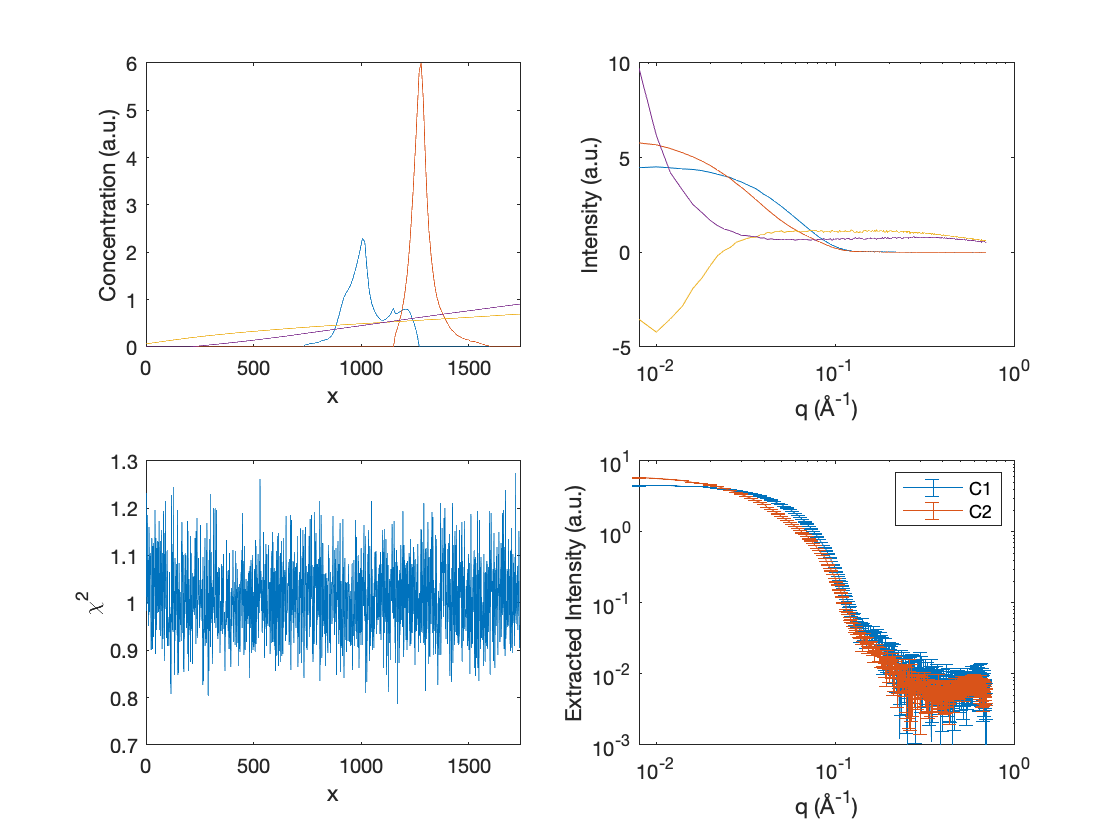

figure(1);clf;
subplot(2,2,1);
plot(M1.concentrations);
set(gca,'Xlim',[0,1738]);xlabel('x');ylabel('Concentration (a.u.)');
subplot(2,2,2);
semilogx(q,M1.profiles);
xlabel('q (Å^{-1})');ylabel('Intensity (a.u.)');
subplot(2,2,3);
plot(mean(resid.^2,1));
set(gca,'Xlim',[0,1738]);xlabel('x');ylabel('\chi^2');
subplot(2,2,4);
errorbar(q,I1,sigma1,'DisplayName','C1');hold on;
errorbar(q,I2,sigma2,'DisplayName','C2');
set(gca,'XScale','Log','Yscale','Log','Ylim',[1E-3,1E1]);
legend show; xlabel('q (Å^{-1})'); ylabel('Extracted Intensity (a.u.)');